# Assignment 2

clear
rng(10)
addpath('functions')

plotPos = [100 100 800, 400];
% fig = figure();
% fig.Position = plotPos;
% tiledlayout(2,1, 'Padding', 'compact', 'TileSpacing', 'compact');
% nexttile;
% hold on
% plot(s14.y_data, 'r', 'LineWidth', 1.5);
% plot(s14.y(1:end), 'b', 'LineWidth', 1.5);
% legend("Legend 1", "Legend 2");
% title('Title');
% xlabel('Time Step');
% ylabel('y_t');
% grid on;
% 
% nexttile;
% plot(s14.u, 'r', 'LineWidth', 1.5);
% title('Control Input u_t');
% xlabel('Time Step');
% ylabel('u_t');
% grid on;
% hold off;
% 
% filename = 'filename.png'
% filePath = fullfile("output/", filename);
% exportgraphics(fig, filePath, 'Resolution', 300);


## Question 1.1

s11.A = [1,-2.438, 1.942,-0.502]

s11 = struct with fields:
    A: [1 -2.4380 1.9420 -0.5020]


s11.B = [1.446, -0.158, -1.093]

s11 = struct with fields:
    A: [1 -2.4380 1.9420 -0.5020]
    B: [1.4460 -0.1580 -1.0930]


s11.C = [1, 0.5,0.75]

s11 = struct with fields:
    A: [1 -2.4380 1.9420 -0.5020]
    B: [1.4460 -0.1580 -1.0930]
    C: [1 0.5000 0.7500]


root = roots(s11.A)

root =     0.9511
    0.9012
    0.5856


abs(root)

ans =     0.9511
    0.9012
    0.5856


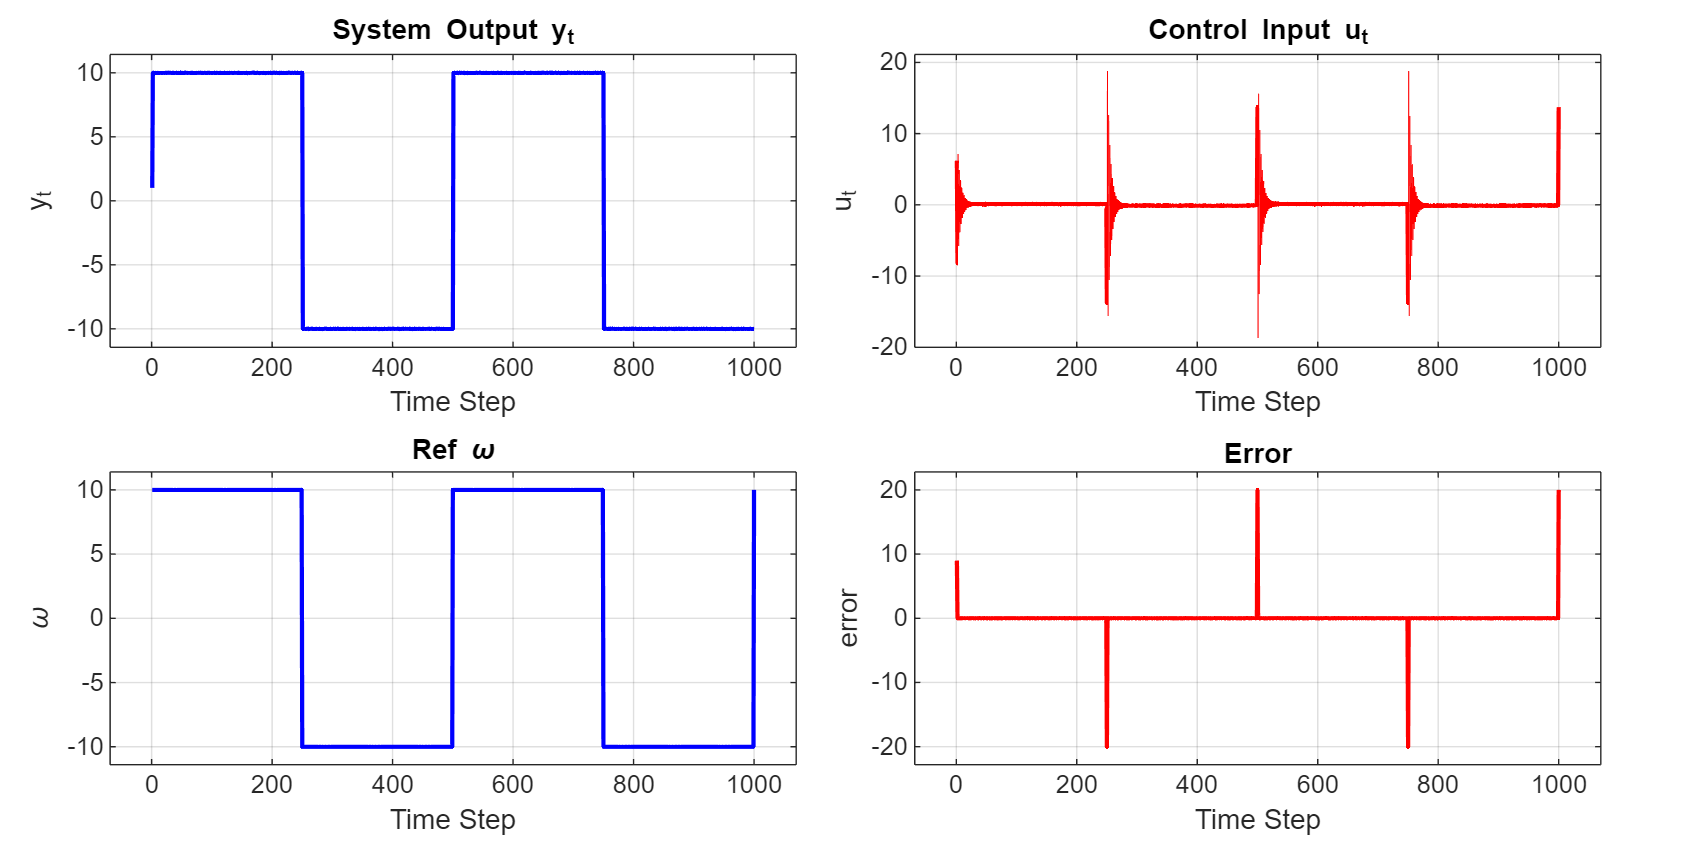

s11.sigma_e = 10^(-2);
s11.N = 1000;
s11.k = 1;
n_max = max([length(s11.A),length(s11.B)]);
s11.u_init = zeros(n_max,1);
s11.y_init = ones(n_max,1);

s11.e = normrnd(0, s11.sigma_e,s11.N,1);
T = s11.N/2; % Periode in sampels
s11.omega = 10*square(2*pi*1/T*(1:s11.N),50)';
s11.rho = 0.01;
[s11.y,s11.u] = MV0(s11.A, s11.B, s11.omega, s11.e, s11.N, s11.k, s11.y_init, s11.u_init);
% [s11.y,s11.u] = ARX(s11.A, s11.B, s11.e, s11.N, s11.k, s11.y_init, s11.u_init, zeros(s11.N,1));
% [s11.y,s11.u] = MV1a(s11.A, s11.B, s11.C, 1, 1, s11.k, s11.rho , s11.omega,s11.e, s11.N);

% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s11`
plotSystemResponse(s11, 1:s11.N, plotPos, filename);

## Question 1.2

## Question 1.3

## Question 1.4

## Question 1.5

## Question 2.4

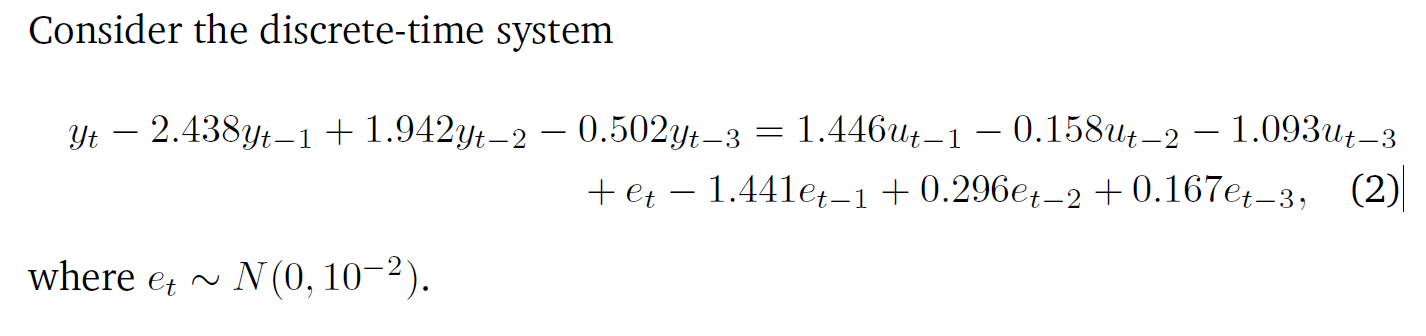

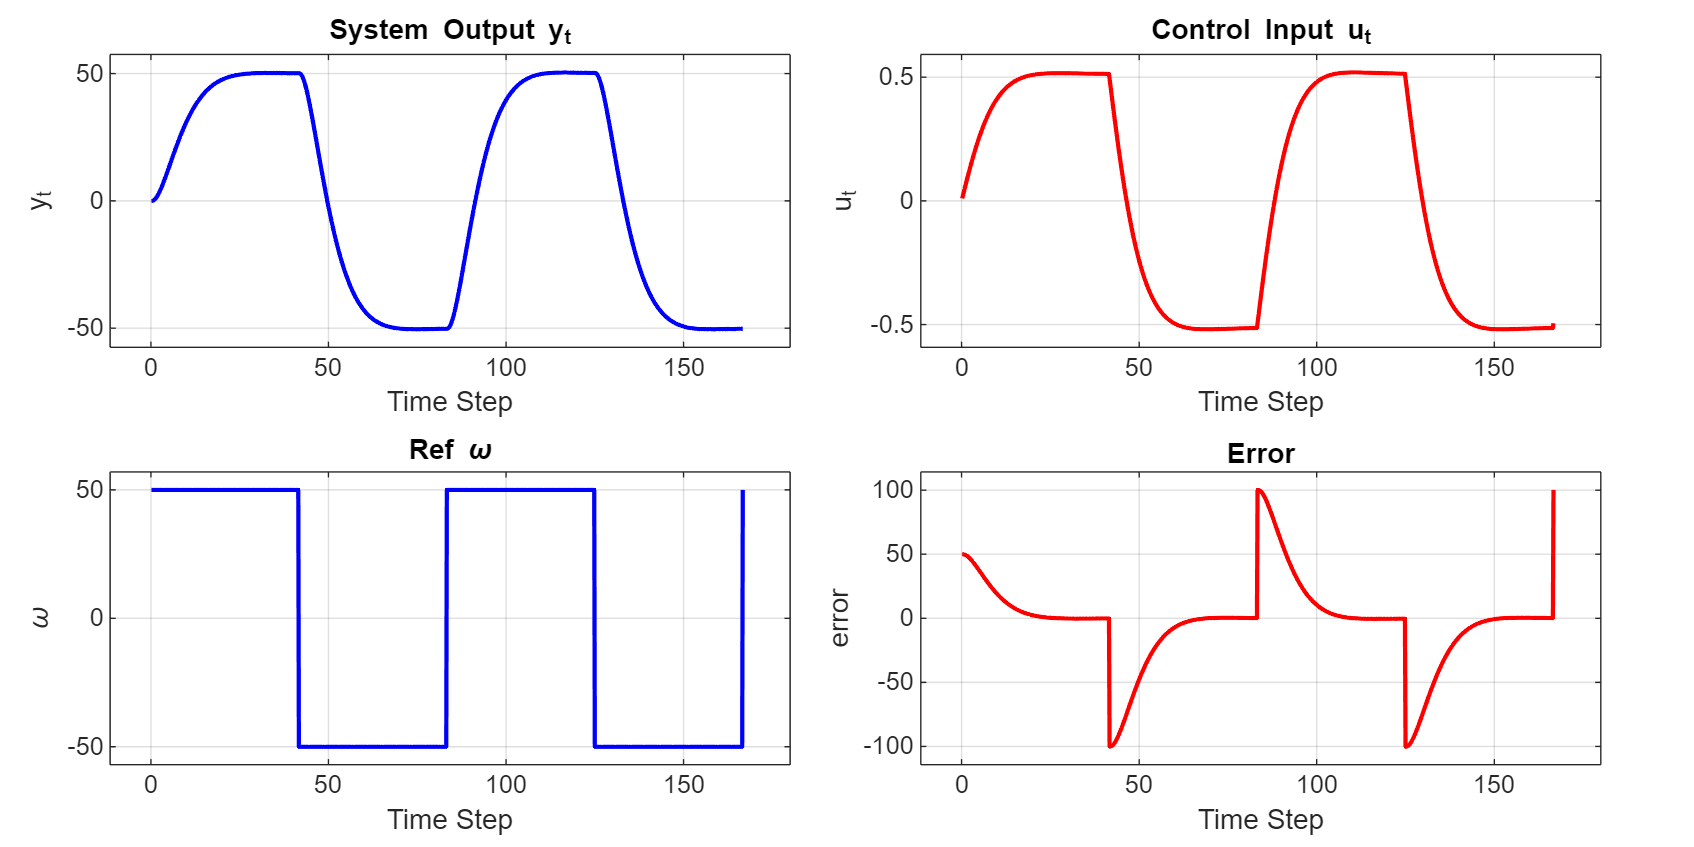

s24.A = [1,-2.438, 1.942,-0.502];
s24.B = [1.446, -0.158, -1.093];
s24.C = [1, -1.441, 0.296, 0.167];
s24.sigma_e = 10^(-2);
% s24.sigma_e = 0.1;
s24.N = 1000;
s24.k = 1;
n_max = max([length(s24.A),length(s24.B)]);
n_max = 5;
s24.u_init = 0*0.01*ones(n_max,1);
s24.y_init = 0*ones(n_max,1);

s24.e = normrnd(0, s24.sigma_e,s24.N,1);
T = s24.N/2; % Periode in sampels
s24.omega = 50*square(2*pi*1/T*(1:s24.N),50)';


Ay = [1];
By = [1]; 
Au = [1]; 
Bu = [1, -1]; % MV1a
Aw = [1]; 
Bw = [1]; 
rho = 7500; % MV1a


[s24.y,s24.u] = GMV(s24.A, s24.B, s24.C, s24.k, s24.omega,s24.e, s24.N, Ay, By, Au, Bu, Aw, Bw, rho,s24.y_init, s24.u_init);
% [s24.y,s24.u] = ARMAX(s24.A, s24.B, s24.C, s24.k,s24.e, s24.N, s24.y_init, s24.u_init);


% Define filename
filename = 'MV0.png';
s24.omega = filter(Bw,Aw,s24.omega);

% Call the function with your data structure `s11`
plotSystemResponse(s24, (1:s24.N)*10/60, plotPos, filename);